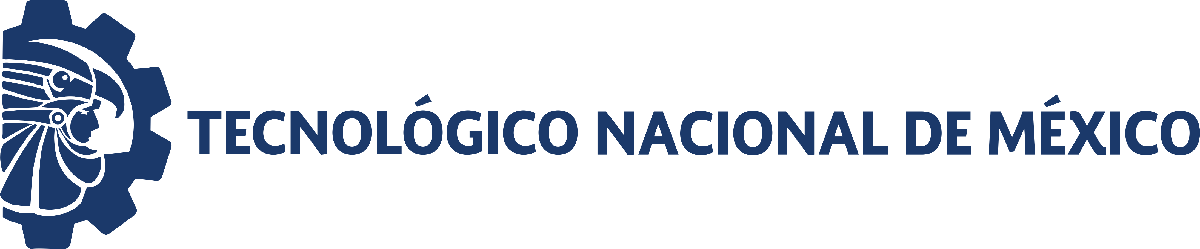                                 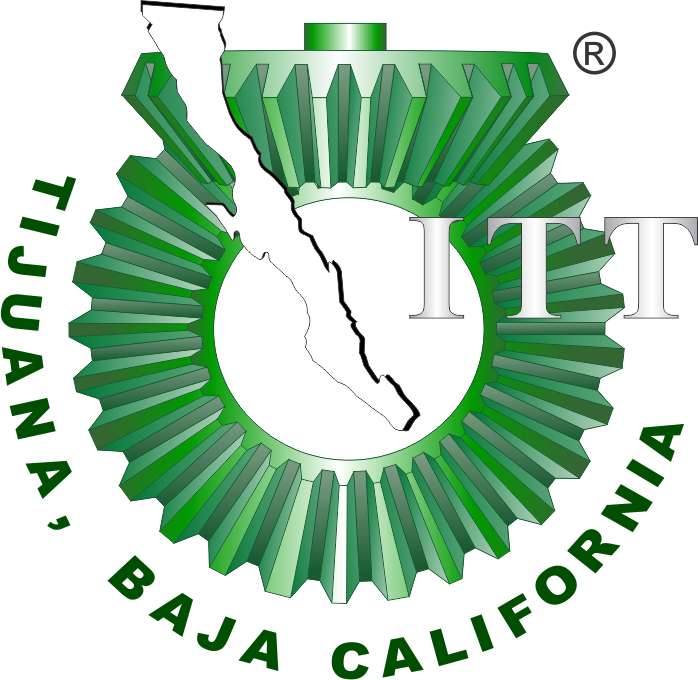

# Práctica 2: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

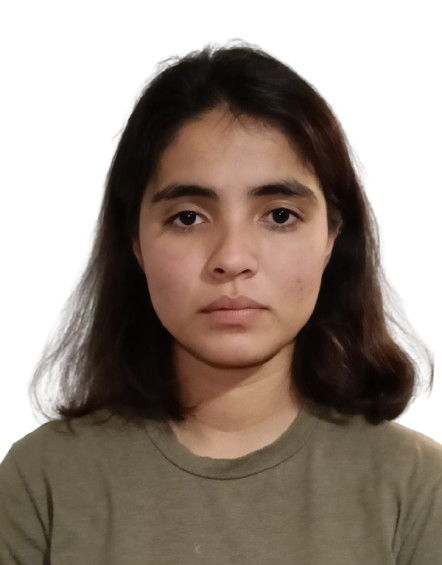

Nombre del alumno: Vania Daniela Rivera Durán

Número de control: C22211720

Correo institucional: L22211720**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file= 'Sistema';
open_system(file);
parameters.StopTime='15';
parameters.Solver='ode15s';
parameters.MaxStep='1E-3';
x = sim(file,parameters);
writematrix(x.Pa,'signal.xlsx');

## Respuesta del sistema

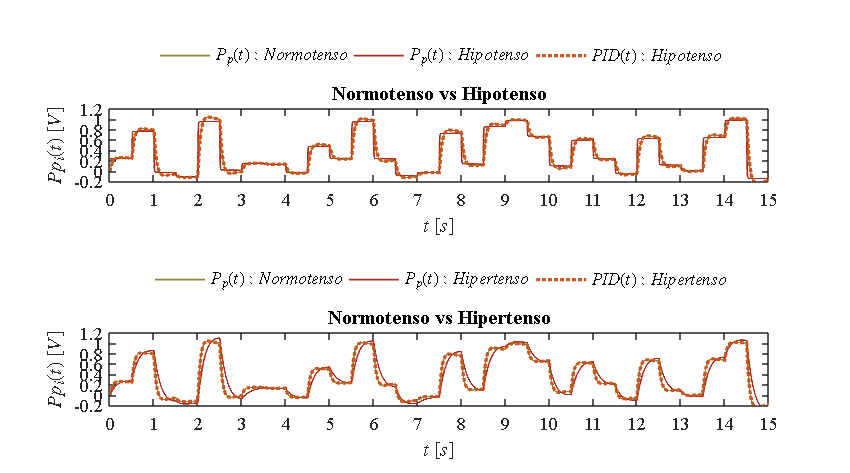

plotsignals(x.t,x.Pp1,x.Pp2,x.Pp3,x.PID1,x.PID2)

## Función: Respuesta a las señales

function plotsignals(t,Pp1,Pp2,Pp3,PID1,PID2)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,10])
    colors = [138, 134, 53;
              170, 43, 29;
              204, 86, 30]/255;
    colororder(colors)

    subplot(2,1,1); hold on; box on;
    P = plot(t,Pp1,'-',t,Pp2,'-',t,PID1,':','LineWidth',1); set (P(3),'LineWidth',2)
    L=legend('$P_p(t): Normotenso$','$P_p(t): Hipotenso$','$PID(t): Hipotenso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','NorthOutside','box','off','Orientation','Horizontal')
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    xlim([0,15]);xticks(0:1:15);
    ylim([-0.2,1.2]);yticks(-0.2:0.2:1.2);
    T = title("Normotenso vs Hipotenso"); set(T,'FontSize',10);
    set(gca,'FontName','Times New Roman','FontSize',11);


    subplot(2,1,2); hold on; box on;
    P = plot(t,Pp1,'-',t,Pp3,'-',t,PID2,':','LineWidth',1); set (P(3),'LineWidth',2)
    L=legend('$P_p(t): Normotenso$','$P_p(t): Hipertenso$','$PID(t): Hipertenso$');
    set(L,'Interpreter','Latex','FontSize',10,'location','NorthOutside','box','off','Orientation','Horizontal')
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    xlim([0,15]);xticks(0:1:15);
    ylim([-0.2,1.2]);yticks(-0.2:0.2:1.2);
    T = title("Normotenso vs Hipertenso"); set(T,'FontSize',10);
    set(gca,'FontName','Times New Roman','FontSize',11);


    exportgraphics(gcf,'Cardiovascular.pdf','ContentType','vector')
    %exportgraphics(gcf,[Signal,'.png'],'Resolution',600)
    %print(Signal, '-dsvg', '-r600')
    %print(Signal, '-depsc', '-r600')

end